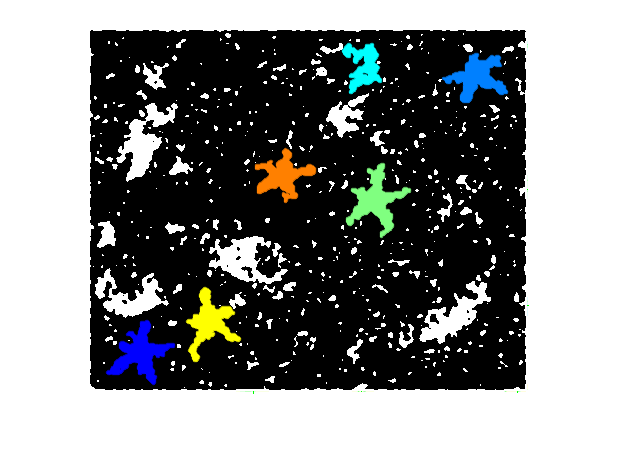

% Clear the workspace
clear
addpath('./functions/');

im = imread("images\starfish_noise7.jpg");
[mask, count] = Process1("images\starfish_noise7.jpg");


% RAW IMAGE texture stats
stats = GetTextureStats(im, mask)

stats = 6×6 table
    AvgGrayLvl    AvgContrst    Smoothness    ThrdMoment    Uniformity    Entropy
    __________    __________    __________    __________    __________    _______

       212.7        37.894       0.021606       -1.2126      0.014589     6.7427 
      211.04         38.46       0.022242       -1.2264      0.013821     6.7934 
      210.87          38.5       0.022287       -1.1589      0.014362     6.7864 
      199.41        38.314       0.022077      -0.49945     0.0093672     7.0314 
       212.6         37.69       0.021379       -1.1941      0.014317     6.7487 
      210.19        40.287       0.024352       -1.3978      0.014344     6.8151 



% No Distinct differences between erroneous regions (even denoised).
% DENOISED texture stats
denoised = Denoise(im);
stats = GetTextureStats(denoised, mask)

stats = 6×6 table
    AvgGrayLvl    AvgContrst    Smoothness    ThrdMoment    Uniformity    Entropy
    __________    __________    __________    __________    __________    _______

      213.96        31.439       0.014973       -0.7136      0.019878     6.2951 
      212.48         32.12       0.015618      -0.79117      0.018542     6.3632 
      212.21         31.78       0.015295      -0.69422      0.017688      6.391 
      200.71        30.151       0.013788      -0.14958      0.011189     6.6613 
      213.93        31.069       0.014628      -0.74036       0.01956      6.302 
      211.67        34.191       0.017661      -0.91847      0.018088     6.4231 



% NB: n == 5 is the erroneous detection.
% [ccs, n] = bwlabeln(mask);